Phys3605 - Fall 2024: Homework 3

**Problem 1: Linear Fit and Kai Squared**

**1.**

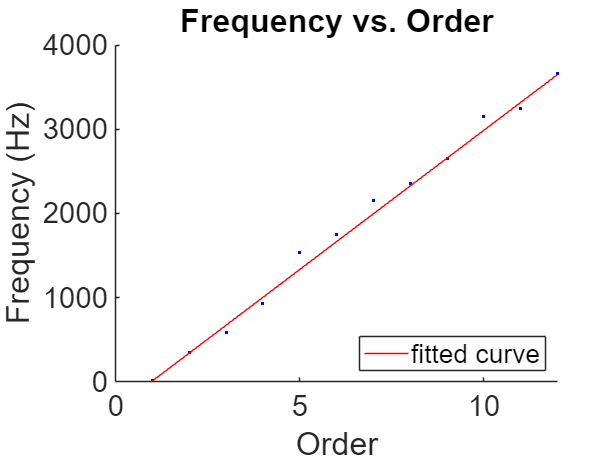

freq = [10, 350, 580, 930, 1530, 1750, 2150, 2350, 2650, 3150, 3250, 3660] ;
freq_err = [10, 35, 60, 80, 150, 180, 220, 300, 260, 320, 320, 360] ;
order = 1:12 ;
weights = 1./freq_err.^2 ;
f = fit(order', freq', 'poly1', 'weights', weights) ;
hold on
plot(order, freq, "b.")
plot(f)
hold off
xlabel('Order')
ylabel('Frequency (Hz)')
set(gca, "fontsize", 20)
legend('Location', 'southeast')
ylim([0, 4000])
xlim([0, 12])
title('Frequency vs. Order')

clf
% Function for calculating linear fit by weighted least squares
function fit = wlsfit(x, y, y_uncer)
    weights = 1 ./ y_uncer.^2
    delta = sum(weights)*sum(weights.*(x.^2)) - (sum(weights.*x))^2 ;
    A = (sum(weights.*x.^2)*sum(weights.*y) - sum(weights.*x)*sum(weights.*x.*y)) / delta ;
    B = (sum(weights)*sum(weights.*x.*y) - sum(weights.*x)*sum(weights.*y)) / delta ; 
    A_err = sqrt(sum(weights.*x.^2) / delta) ;
    B_err = sqrt(sum(weights) / delta) ;
    fit = [A, B, A_err, B_err] ;
end
wlsf = wlsfit(order, freq, freq_err)

weights =     0.0100    0.0008    0.0003    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


wlsf =  -322.4178  331.1524   16.0520   10.4928


fit_line = wlsf(1) + wlsf(2)*order

fit_line = 1.0e+03 *

    0.0087    0.3399    0.6710    1.0022    1.3333    1.6645    1.9956    2.3268    2.6580    2.9891    3.3203    3.6514


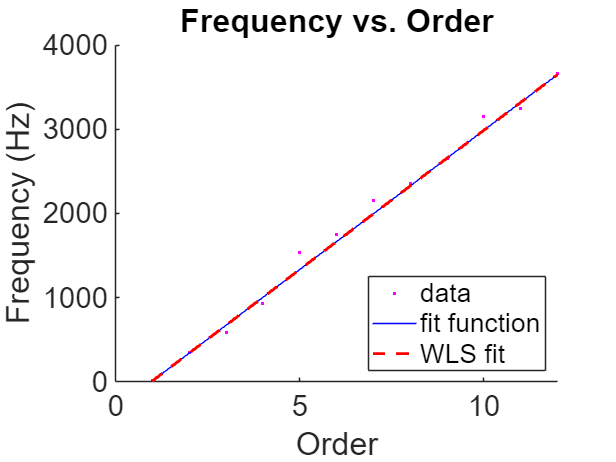

hold on
plot(order, freq, 'm.', 'LineWidth', 2)
plot(f, 'b')
plot(order, fit_line, 'r--', 'LineWidth', 2)
hold off
xlabel('Order')
ylabel('Frequency (Hz)')
set(gca, "fontsize", 20)
legend('data', 'fit function', 'WLS fit','Location', 'southeast')
ylim([0, 4000])
xlim([0, 12])
title('Frequency vs. Order')

% Function for finding chi-square and reduced chi-square with poly1 as the
% fit
function chi = findChi(x, y, y_uncer, A, B)
    chi_square = sum((y - A - B.* x) / y_uncer.^2 ) ;
    reduced_chi_square = chi_square / (length(y) - 2) ;
    chi = [chi_square, reduced_chi_square] ;
end
chi_squares = findChi(order, freq, freq_err, wlsf(1), wlsf(2))

chi_squares = 1.0e-03 *

    0.4749    0.0475
